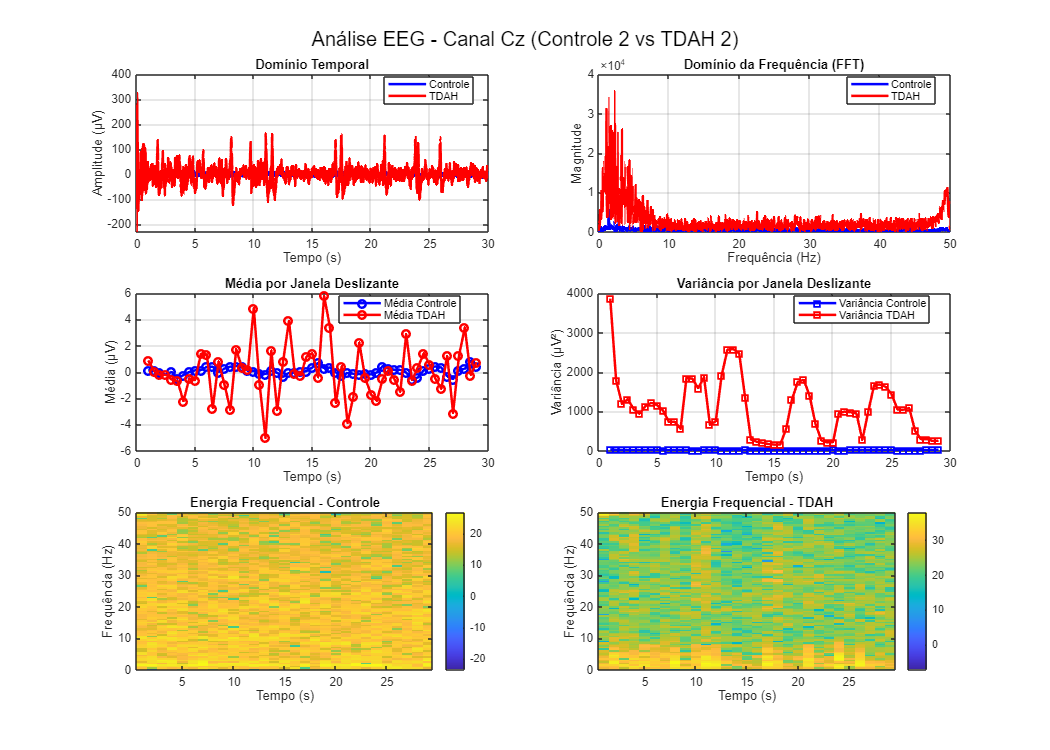

% Análise EEG Simples - TDAH vs Controle (Feminino)
% 4 análises principais conforme solicitado

clear; clc; close all;

% Carregar dados
load('FC.mat');    % Controles femininos
load('FADHD.mat'); % TDAH femininos

% Parâmetros
fs = 256;  % Frequência de amostragem
task = 1;  % Eyes open baseline

% Extrair dados e remover sujeito corrompido
controle_data = FC{task};
adhd_data = FADHD{task};
adhd_data(7,:,:) = [];

max_diff = 0;
melhor_controle = 1;
melhor_adhd = 1;
melhor_canal = 1;

% Buscar casos mais discrepantes (código simples)
for canal = 1:2  % 2 canais: Cz, F4
    for i = 1:size(controle_data,1)
        for j = 1:size(adhd_data,1)
            % Sinais
            si_controle = squeeze(controle_data(i,:,canal));
            si_adhd = squeeze(adhd_data(j,:,canal));
            
            % FFT simples
            fft_controle = abs(fft(si_controle));
            fft_adhd = abs(fft(si_adhd));
            
            % Diferença (1-50 Hz)
            freq_idx = round(length(fft_controle)/2);
            diff = sum(abs(fft_adhd(1:freq_idx) - fft_controle(1:freq_idx)));
            
            if diff > max_diff
                max_diff = diff;
                melhor_c = i;
                melhor_a = j;
                melhor_canal = canal;
            end
        end
    end
end

melhor_c = 2; %o melhor controle é 2 (mudar código de procura depois)

% Sinais selecionados
si_controle = squeeze(controle_data(melhor_c,:,melhor_canal));
si_adhd = squeeze(adhd_data(melhor_a,:,melhor_canal));
canal_nome = {'Cz', 'F4'};

% Preparar dados
t = (0:length(si_controle)-1)/fs;
N = length(si_controle);
freq = (0:N/2-1)*(fs/N);

% FFT
fft_controle = abs(fft(si_controle));
fft_adhd = abs(fft(si_adhd));
fft_controle = fft_controle(1:N/2);
fft_adhd = fft_adhd(1:N/2);

% FIGURA PRINCIPAL
figure('Position', [50, 50, 1400, 1000]);

% 1. DOMÍNIO TEMPORAL E FREQUENCIAL
subplot(3,2,1);
plot(t, si_controle, 'b-', 'LineWidth', 2, 'DisplayName', 'Controle');
hold on;
plot(t, si_adhd, 'r-', 'LineWidth', 2, 'DisplayName', 'TDAH');
xlabel('Tempo (s)');
ylabel('Amplitude (μV)');
title('Domínio Temporal');
legend('Location', 'best');
grid on;

subplot(3,2,2);
plot(freq, fft_controle, 'b-', 'LineWidth', 2, 'DisplayName', 'Controle');
hold on;
plot(freq, fft_adhd, 'r-', 'LineWidth', 2, 'DisplayName', 'TDAH');
xlabel('Frequência (Hz)');
ylabel('Magnitude');
title('Domínio da Frequência (FFT)');
legend('Location', 'best');
xlim([0 50]);
grid on;

% 2. MÉDIA E VARIÂNCIA POR JANELA DESLIZANTE
janela = round(fs * 2);  % Janela de 2 segundos
passo = round(janela/4); % Passo de 0.5 segundos
num_janelas = floor((N - janela)/passo) + 1;

media_controle = zeros(1, num_janelas);
var_controle = zeros(1, num_janelas);
media_adhd = zeros(1, num_janelas);
var_adhd = zeros(1, num_janelas);
t_janelas = zeros(1, num_janelas);

for i = 1:num_janelas
    inicio = (i-1)*passo + 1;
    fim = inicio + janela - 1;
    
    janela_c = si_controle(inicio:fim);
    janela_a = si_adhd(inicio:fim);
    
    media_controle(i) = mean(janela_c);
    var_controle(i) = var(janela_c);
    media_adhd(i) = mean(janela_a);
    var_adhd(i) = var(janela_a);
    
    t_janelas(i) = (inicio + fim)/(2*fs);  % Tempo central da janela
end

subplot(3,2,3);
plot(t_janelas, media_controle, 'b-o', 'LineWidth', 2, 'DisplayName', 'Média Controle');
hold on;
plot(t_janelas, media_adhd, 'r-o', 'LineWidth', 2, 'DisplayName', 'Média TDAH');
xlabel('Tempo (s)');
ylabel('Média (μV)');
title('Média por Janela Deslizante');
legend('Location', 'best');
grid on;

subplot(3,2,4);
plot(t_janelas, var_controle, 'b-s', 'LineWidth', 2, 'DisplayName', 'Variância Controle');
hold on;
plot(t_janelas, var_adhd, 'r-s', 'LineWidth', 2, 'DisplayName', 'Variância TDAH');
xlabel('Tempo (s)');
ylabel('Variância (μV²)');
title('Variância por Janela Deslizante');
legend('Location', 'best');
grid on;

% 3. ENERGIA DAS FREQUÊNCIAS AO LONGO DO TEMPO (ESPECTROGRAMA)
subplot(3,2,5);
window = 512;
overlap = 256;
[S_controle, F, T] = spectrogram(si_controle, window, overlap, [], fs);
imagesc(T, F, 10*log10(abs(S_controle)));
axis xy;
xlabel('Tempo (s)');
ylabel('Frequência (Hz)');
title('Energia Frequencial - Controle');
colorbar;
ylim([0 50]);

subplot(3,2,6);
[S_adhd, F, T] = spectrogram(si_adhd, window, overlap, [], fs);
imagesc(T, F, 10*log10(abs(S_adhd)));
axis xy;
xlabel('Tempo (s)');
ylabel('Frequência (Hz)');
title('Energia Frequencial - TDAH');
colorbar;
ylim([0 50]);

sgtitle(sprintf('Análise EEG - Canal %s (Controle %d vs TDAH %d)', ...
        canal_nome{melhor_canal}, melhor_c, melhor_a), 'FontSize', 16);


% 4. MÉTRICAS ESPECTRAIS ESPECÍFICAS
fprintf('\n=== MÉTRICAS ESPECTRAIS ===\n');


=== MÉTRICAS ESPECTRAIS ===


fprintf('Canal: %s\n', canal_nome{melhor_canal});

Canal: Cz


fprintf('Controle: Sujeito %d | TDAH: Sujeito %d\n\n', melhor_c, melhor_a);

Controle: Sujeito 2 | TDAH: Sujeito 2




% Faixas de frequência padrão EEG
faixas = {'Delta (0.5-4 Hz)', 'Theta (4-8 Hz)', 'Alpha (8-12 Hz)', 'Beta (12-30 Hz)', 'Gamma (30-50 Hz)'};
limites = [0.5 4; 4 8; 8 12; 12 30; 30 50];

fprintf('FAIXA\t\t\tCONTROLE\tTDAH\t\tDIFERENÇA\n');

FAIXA			CONTROLE	TDAH		DIFERENÇA


fprintf('--------------------------------------------------------\n');

--------------------------------------------------------



for i = 1:5
    idx = freq >= limites(i,1) & freq <= limites(i,2);
    power_c = sum(fft_controle(idx).^2);
    power_a = sum(fft_adhd(idx).^2);
    diff_pct = ((power_a - power_c) / power_c) * 100;
    
    fprintf('%-15s\t%.2e\t%.2e\t%+.1f%%\n', faixas{i}, power_c, power_a, diff_pct);
end

Delta (0.5-4 Hz)	1.49e+08	2.06e+10	+13762.5%
Theta (4-8 Hz) 	5.86e+07	4.85e+09	+8170.3%
Alpha (8-12 Hz)	7.28e+07	5.08e+08	+598.2%
Beta (12-30 Hz)	1.89e+08	1.79e+09	+845.1%
Gamma (30-50 Hz)	9.56e+07	4.56e+09	+4671.3%



% Métricas adicionais
power_total_c = sum(fft_controle.^2);
power_total_a = sum(fft_adhd.^2);
freq_pico_c = freq(fft_controle == max(fft_controle));
freq_pico_a = freq(fft_adhd == max(fft_adhd));

fprintf('\n--- MÉTRICAS GERAIS ---\n');


--- MÉTRICAS GERAIS ---


fprintf('Potência Total - Controle: %.2e\n', power_total_c);

Potência Total - Controle: 6.07e+08


fprintf('Potência Total - TDAH: %.2e\n', power_total_a);

Potência Total - TDAH: 3.49e+10


fprintf('Frequência Dominante - Controle: %.1f Hz\n', freq_pico_c(1));

Frequência Dominante - Controle: 1.4 Hz


fprintf('Frequência Dominante - TDAH: %.1f Hz\n', freq_pico_a(1));

Frequência Dominante - TDAH: 2.2 Hz



% Razão Theta/Beta (importante para TDAH)
idx_theta = freq >= 4 & freq <= 8;
idx_beta = freq >= 12 & freq <= 30;
ratio_tb_c = sum(fft_controle(idx_theta).^2) / sum(fft_controle(idx_beta).^2);
ratio_tb_a = sum(fft_adhd(idx_theta).^2) / sum(fft_adhd(idx_beta).^2);

fprintf('\n--- RAZÃO THETA/BETA (Indicador TDAH) ---\n');


--- RAZÃO THETA/BETA (Indicador TDAH) ---


fprintf('Controle: %.3f\n', ratio_tb_c);

Controle: 0.310


fprintf('TDAH: %.3f\n', ratio_tb_a);

TDAH: 2.714


fprintf('Diferença: %.3f (%.1f%% maior)\n', ratio_tb_a - ratio_tb_c, ...
        ((ratio_tb_a - ratio_tb_c) / ratio_tb_c) * 100);

Diferença: 2.404 (775.1% maior)
